clc, clear, close all
rng(100);           
run('definitions.m');

VLP definitions and parameters loaded successfully


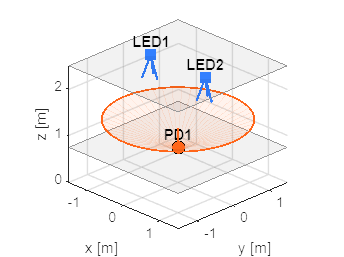


mode = 'two_beamsteering_LED';
AP = AP_config.(mode);
run('fig_setup.m') % ===> MEJORAR LA FUNCION PARA Q SE MUETREN LAS ORIETNACIONS


% channel.sigma2 = 0;

Nsamples = 1000;     % muestras por posición y por AP
S_min = 1e-12 ; % evitar potencias negativas

% Ground truth positions
xv = testbed.x(1):testbed.gridstep:testbed.x(2);
yv = testbed.y(1):testbed.gridstep:testbed.y(2);
[X, Y] = meshgrid(xv, yv);

Npos = numel(X);
Nori = size(AP(1).set_n_t, 1);
Nap  = numel(AP);
S_r  = cell(Npos, Nap, Nori);
SNR  = cell(Npos, Nap, Nori);

UE_n_r = zeros(Npos, 3);
for i_pos = 1:Npos
    UE.pos(1:2) = [X(i_pos), Y(i_pos)];
    UE.n_r = -angles2vec([randi(UE.delta_tilt+1)-1, randi(360)]); % error:PD tilt
    UE_n_r(i_pos,:) = UE.n_r;

    for i_ap = 1:Nap
        for i_ori = 1:Nori
            AP(i_ap).n_t = angles2vec( AP(i_ap).set_n_t(i_ori,:) );
            h0 = h_LOS(AP(i_ap), UE, channel.model);
            S_0 = UE.R_pd * AP(i_ap).P_t * h0;
            w_noise  = sqrt(channel.sigma2) * randn(1, Nsamples);
            S_samples = S_0 + w_noise;
            S_samples = max(S_samples, S_min);
            S_r{i_pos, i_ap, i_ori} = S_samples;
            SNR{i_pos, i_ap, i_ori} = 10*log10( S_0^2 / channel.sigma2);
        end
    end
end

SNR_mean_AP1 = mean(cellfun(@(x) mean(x), SNR(:,:,1)));
fprintf('SNR mean AP1 %.1f dB', SNR_mean_AP1);

SNR mean AP1 -Inf dBSNR mean AP1 -Inf dB

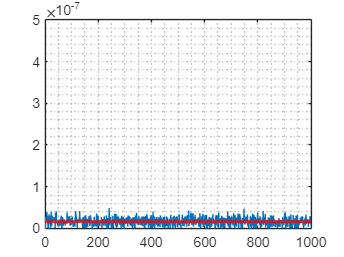


figure
plot(S_0 + w_noise)
yline(S_0,'r','LineWidth',2)
yaxis([0 5e-7])
grid minor

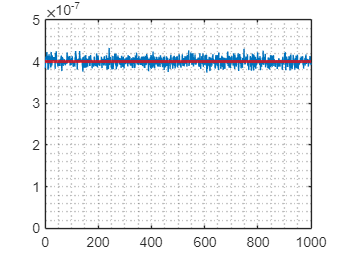


S_r_max = 4e-7;
figure
plot(S_r_max + w_noise)
yline(S_r_max,'r','LineWidth',2)
yaxis([0 5e-7])
grid minor

**One Orientation**

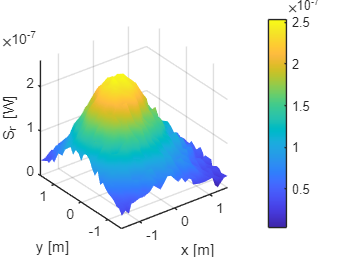

figure
S_r_mean_AP1 = cellfun(@(x) mean(x), S_r(:,1,1));
surf(X, Y, reshape(S_r_mean_AP1, size(X)));
xlabel('x [m]'); ylabel('y [m]'); zlabel('S_r [W]');
shading interp; colorbar;
xlim([testbed.x(1) testbed.x(2)])
ylim([testbed.y(1) testbed.y(2)])
zlim([0 2.6e-7])

**Obtaining the mean**

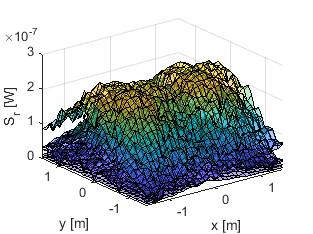

S_r_mean = zeros(Npos, Nap, Nori);
for i_ap = 1:Nap
    for i_ori = 1:Nori
        S_r_mean(:, i_ap, i_ori) = cellfun(@(x) mean(x), S_r(:, i_ap, i_ori));
    end
end

figure
surf(X, Y, reshape(S_r_mean(:,1,1), size(X)),FaceAlpha=0.4);
hold on
surf(X, Y, reshape(S_r_mean(:,1,2), size(X)),FaceAlpha=0.4);
surf(X, Y, reshape(S_r_mean(:,1,3), size(X)),FaceAlpha=0.4);
xlabel('x [m]'); ylabel('y [m]'); zlabel('S_r [W]');
%shading interp; %colorbar;
xlim([testbed.x(1) testbed.x(2)])
ylim([testbed.y(1) testbed.y(2)])
zlim([0 3e-7])


surf(X, Y, reshape(S_r_mean(:,2,1), size(X)),FaceAlpha=0.4);
hold on
surf(X, Y, reshape(S_r_mean(:,2,2), size(X)),FaceAlpha=0.4);
surf(X, Y, reshape(S_r_mean(:,2,3), size(X)),FaceAlpha=0.4);
xlabel('x [m]'); ylabel('y [m]'); zlabel('S_r [W]');
%shading interp; %colorbar;
xlim([testbed.x(1) testbed.x(2)])
ylim([testbed.y(1) testbed.y(2)])
zlim([0 3e-7])

**Projection in 2D**

nlin = 1

nlin = 1

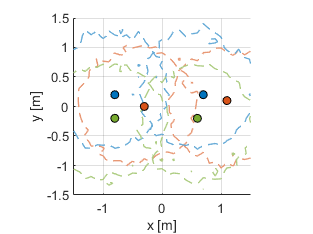

figure
hold on

alpha_val = 0.6;  
colors = [ 0.85 0.33 0.10;  
           0.00 0.45 0.74;  
           0.47 0.67 0.19]; 

bg = [1 1 1];
blend = @(c,a) (1-a)*bg + a*c;
c1 = blend(colors(1,:), alpha_val);
c2 = blend(colors(2,:), alpha_val);
c3 = blend(colors(3,:), alpha_val);

contour(X, Y, reshape(S_r_mean(:,1,1), size(X)), nlin, 'LineWidth', 1, 'LineColor', c1, 'LineStyle','--');
contour(X, Y, reshape(S_r_mean(:,1,2), size(X)), nlin, 'LineWidth', 1, 'LineColor', c2, 'LineStyle','--');
contour(X, Y, reshape(S_r_mean(:,1,3), size(X)), nlin, 'LineWidth', 1, 'LineColor', c3, 'LineStyle','--');

contour(X, Y, reshape(S_r_mean(:,2,1), size(X)), nlin, 'LineWidth', 1, 'LineColor', c1, 'LineStyle','--');
contour(X, Y, reshape(S_r_mean(:,2,2), size(X)), nlin, 'LineWidth', 1, 'LineColor', c2, 'LineStyle','--');
contour(X, Y, reshape(S_r_mean(:,2,3), size(X)), nlin, 'LineWidth', 1, 'LineColor', c3, 'LineStyle','--');

for i_ap=1:Nap
for k = 1:3
    Z = reshape(S_r_mean(:,i_ap,k), size(X));
    [~, idx] = max(Z(:));
    plot(X(idx), Y(idx), 'o', 'MarkerFaceColor', colors(k,:), 'MarkerEdgeColor', 'k');
end
end

hold off
xlabel('x [m]'); ylabel('y [m]');
grid on
axis equal tight

**Model-based estimation**

est_pos = zeros(Npos, 2);
true_pos = [X(:), Y(:)];

for i_pos = 1:Npos

    h_vert = AP(1).pos(3)-UE.pos(3);

    try
        % Estimacion por el AP1
        i_ap = 1;
        S_r_i = squeeze(S_r_mean(i_pos, i_ap, :)); 
        n_d = estimate_direction(S_r_i', angles2vec(AP(i_ap).set_n_t), AP(i_ap).m, 'svd');
        escale = -h_vert/n_d(3);
        est_pos_ap1 = AP(i_ap).pos(1:2) + escale*n_d(1:2);
        
        S_1 = sum(S_r_i);

        % Estimacion por el AP2
        i_ap = 2;
        S_r_i = squeeze(S_r_mean(i_pos, i_ap, :));
        n_d = estimate_direction(S_r_i', angles2vec(AP(i_ap).set_n_t), AP(i_ap).m, 'svd');
        escale = -h_vert/n_d(3);
        est_pos_ap2 = AP(i_ap).pos(1:2) + escale*n_d(1:2);

        S_2 = sum(S_r_i);

        if ( S_1 > S_2 )
            est_pos(i_pos,:)= est_pos_ap1;
        else
            est_pos(i_pos,:)= est_pos_ap2;
        end

    catch
        est_pos(i_pos,:)= [NaN, NaN];
    end

end

**Show results**

APE  : 0.795 cm
RMSE : 1.033 cm
CDF_90 : 1.673 cm


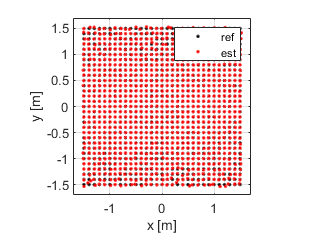

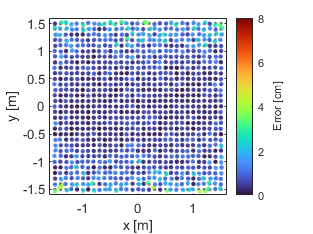

run('show_metrics.m');

**Estimation of the UE orientations**

est_n_r  = zeros(Npos, 3);

for i_pos=1:Npos

    % evaluation of FOV
%     d_AP1_UE = norm(true_pos(i_pos,:)-AP(1).pos(1:2));
%     d_AP2_UE = norm(true_pos(i_pos,:)-AP(2).pos(1:2));
%     phi_AP1_UE = atand(d_AP1_UE/h_vert);
%     phi_AP2_UE = atand(d_AP2_UE/h_vert);

    Pr1 = squeeze(S_r_mean(i_pos, 1, :));  % vector K1x1
    Pr2 = squeeze(S_r_mean(i_pos, 2, :));  % vector K2x1
    K1  = numel(Pr1); K2 = numel(Pr2);

    if (1==0) % FOV !!
        est_n_r(i_pos,:) = [NaN,NaN,NaN];
    else
        Kmax = max(K1,K2);
        Pblock = NaN(Kmax,2);
        Pblock(1:K1,1) = Pr1;
        Pblock(1:K2,2) = Pr2;
    
        %est_xy = est_pos(i_pos,:);
        est_xy = true_pos(i_pos,:);
        p_est_xyz = [est_xy, UE.pos(3)];  % reconstruye (x,y,z)
        n_r_est = estimate_UE_orientation(AP, UE, p_est_xyz, Pblock);      
        est_n_r(i_pos,:) = n_r_est;
    end

end

cosdiff = dot(UE_n_r,est_n_r,2);
cosdiff = min(cosdiff,1);
thetadiff = acosd(cosdiff);

APE_orientation = mean(thetadiff)

APE_orientation = 1.6337

RMSE_orientation = sqrt(mean(thetadiff.^2))

RMSE_orientation = 5.7109

CDF90_orientation = prctile(thetadiff, 90)

CDF90_orientation = 2.0732

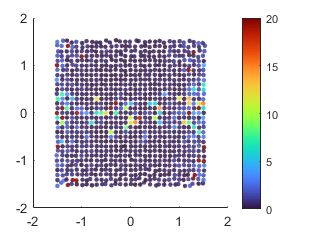


figure; hold on
scatter(est_pos(:,1), est_pos(:,2), 12, thetadiff, 'filled', ...
    'MarkerFaceAlpha', 0.85);  % suaviza el punto
colormap(turbo);
caxis([cmin 20]);       
colorbar



idx=(thetadiff<5);
mean(thetadiff(idx))

ans = 0.5362

sqrt(mean(thetadiff(idx).^2))

ans = 0.8560

prctile(thetadiff(idx), 90)

ans = 1.2899

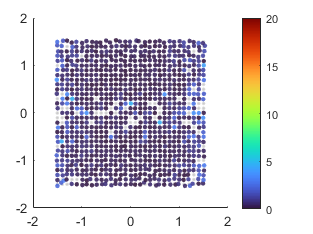

figure; hold on
plot(true_pos(:,1), true_pos(:,2), '.', 'Color', [0.8 0.8 0.8]);
scatter(est_pos(idx,1), est_pos(idx,2), 12, thetadiff(idx), 'filled', ...
    'MarkerFaceAlpha', 0.85);  % suaviza el punto
colormap(turbo);
caxis([cmin 20]);       
colorbar